# Create and Customize 3-D Scatter Plots

`Scatter3` displays circles at specified `x, y, and z `locations.

### Create a 3-D Dataset

Reference the built in sphere function to create `X`, `Y`, and `Z`, matrices and create three layers of the data at $0\ldotp 5x$ scale $0\ldotp 75x$ scale, and the standard scaling. This will create a sphere of layered points defined in the arrays `x`, `y`, and `z`.

[X,Y,Z] = sphere(16);
x = [0.5*X(:); 0.75*X(:); X(:)];
y = [0.5*Y(:); 0.75*Y(:); Y(:)];
z = [0.5*Z(:); 0.75*Z(:); Z(:)];

### Basic Plot

Pass the three matrixes to the scatter3 function to create the sphere point cloud.

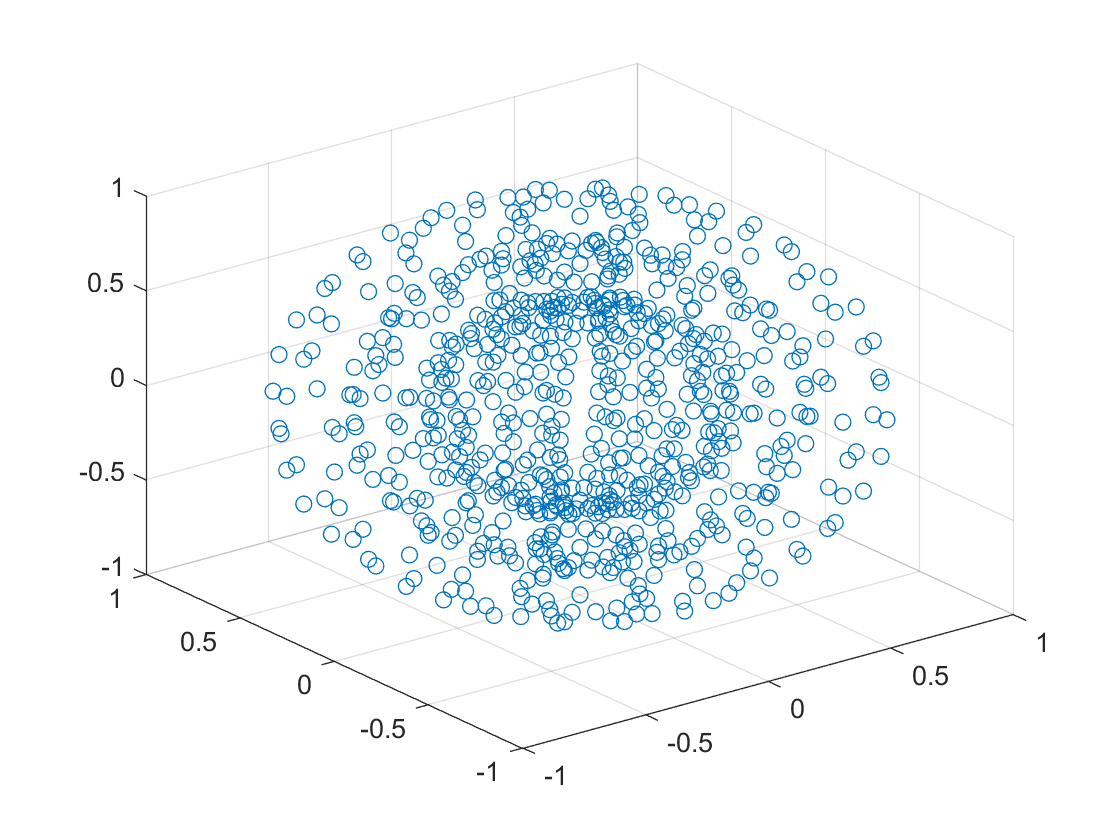

scatter3(x,y,z)

## Customizations

### Specify Point Size and Type

The point size can be set for individual points by passing a vector of sizes corresponding to each point, or a global size can be specified using the *SizeData* property. Additionally, the point's appearance can be changed to various other shapes and appearances through the *Marker *property.

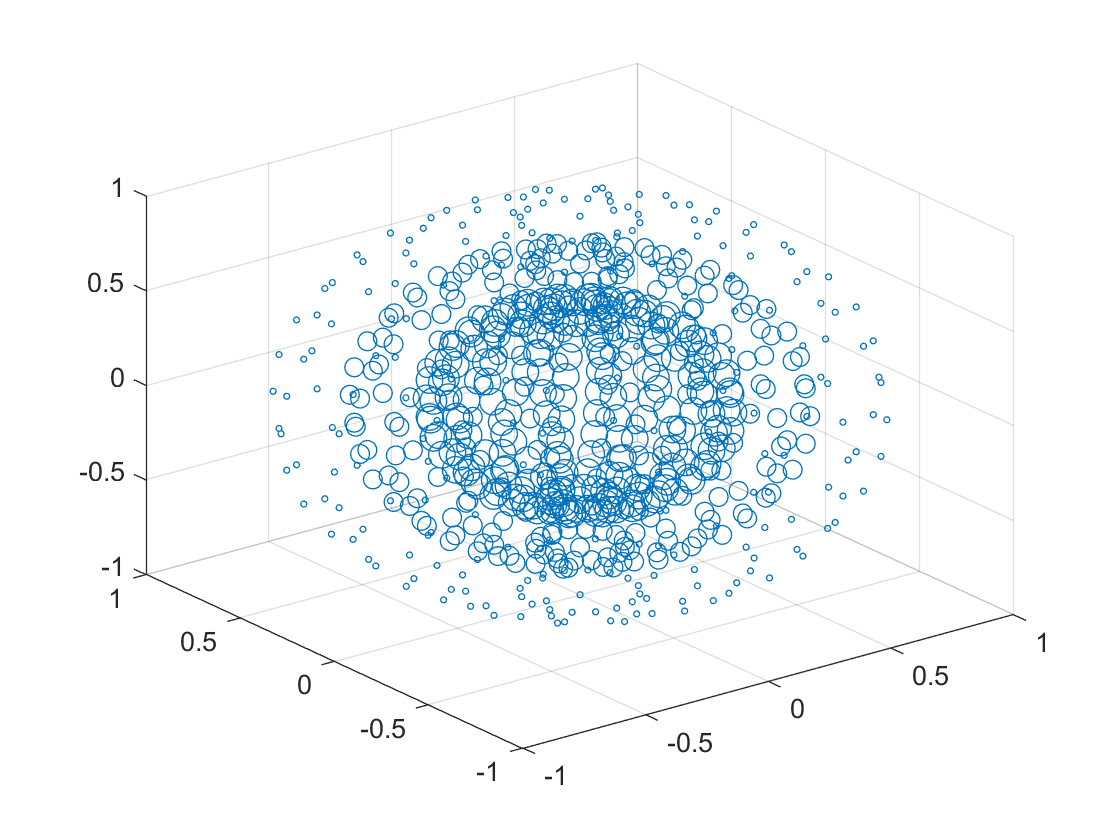

MarkerType = 'o';
S = repmat([100,50,5],length(X),1);
s = S(:);
scatter3(x,y,z, ...
    "SizeData", s,...                % Set the size property to the defined matrix
    "Marker", MarkerType)            % Specify the marker type

### Change Marker Color 

Similar to the size, a vector containing color options can be used to specify the color of each individual point as the Marker Color input. Additionally, to visualize the colors with more clarity, the *filled *property can be applied to fill empty space within each point. The *MarkerEdgeColor *and *MarkerFaceColor *can be set to predefined RGB set that is applied to all the points.

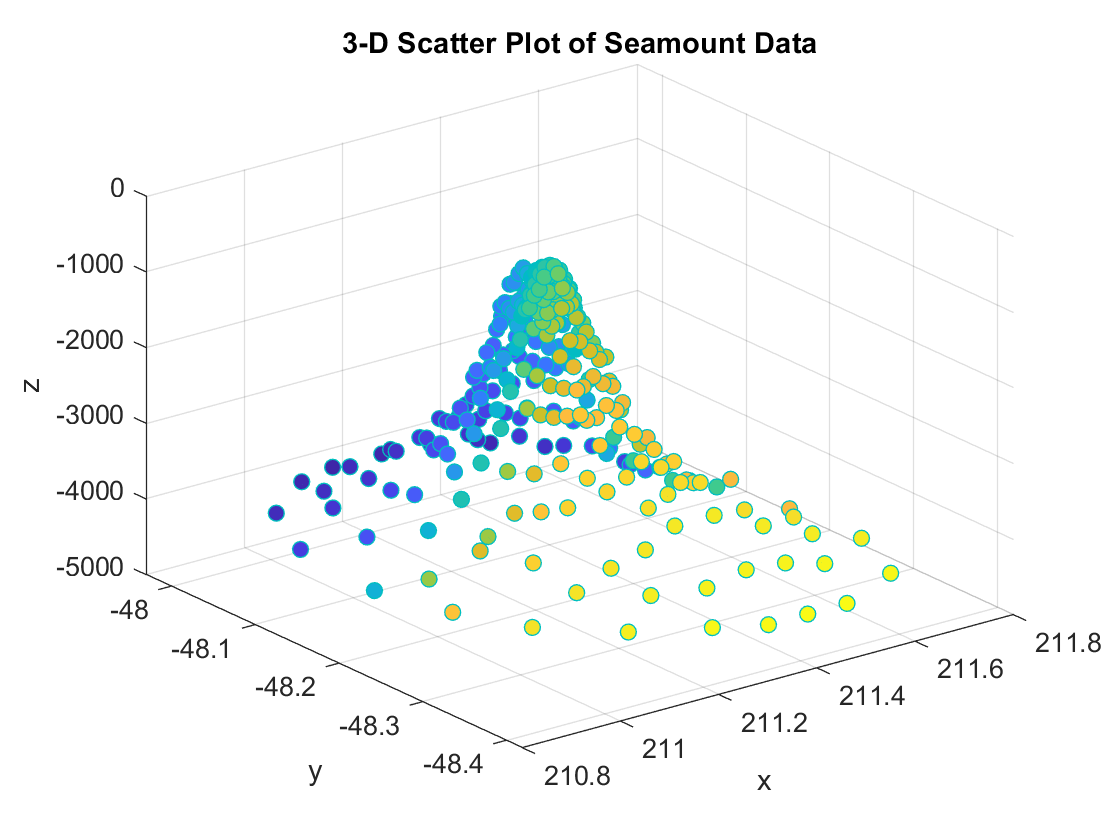

load seamount
C = parula(length(x));
figure
s3 = scatter3(x,y,z,[], C,...           % Provide the parula colormap to the Marker Color input
    "filled",...                        % Enable filling
    "MarkerEdgeColor",[0 .75 .75]);     % Specify an edge color for all points

title('3-D Scatter Plot of Seamount Data');
xlabel("Longitude")
ylabel("Latitude")
zlabel("Depth (feet)")

## Additional Information

### Get All Scatter Properties

Graphics objects in MATLAB have many properties. To see all the properties of a scatter3, uncomment the following code

% get(s3)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[scatter3](https://www.mathworks.com/help/matlab/ref/scatter3.html)